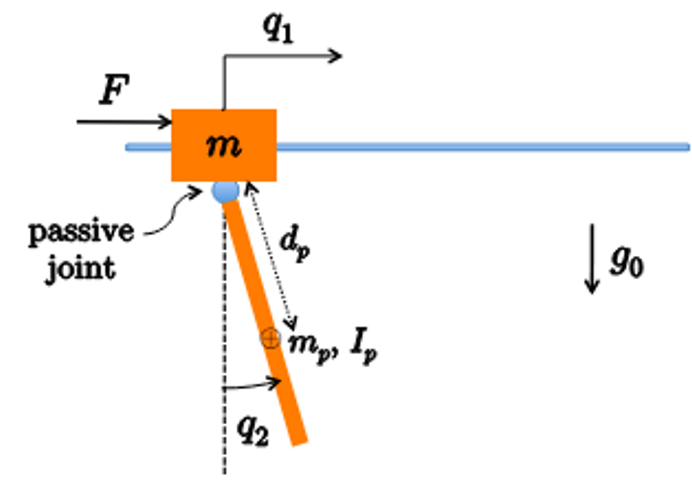

## Point 1

syms q1 q2 q_dot_1 q_dot_2 real
syms m m_p I_p d_p g0 positive
syms a1 a2 a3

% Joint 1 
T1 = 0.5*m*q_dot_1^2

$$T1 = \frac{m\,{{\dot{q}}_{1}}^{2}}{2}$$


% Joint 2
x2 = q1+d_p*sin(q2);
y2 = d_p*cos(q2);

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2;
vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2;

T2_tr = 0.5*m_p*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*I_p*[0 0 q_dot_2]*[0; 0; q_dot_2;];
T2 = T2_tr+T2_rot

$$T2 = \frac{m_{p}\,{\left({\dot{q}}_{1}+d_{p}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{p}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{d_{p}}^{2}\,m_{p}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


% total energy
T = T1+T2;

% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = [M11, M12;
     M21, M22;];
M = simplify(M)

$$M = \left(\begin{array}{cc} m+m_{p} & d_{p}\,m_{p}\,\cos\left(q_{2}\right)\\ d_{p}\,m_{p}\,\cos\left(q_{2}\right) & m_{p}\,{d_{p}}^{2}+I_{p} \end{array}\right)$$


% Gravity terms
U1 = 0;
U2 = m_p*g0*y2;

U = [U1+U2];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} 0\\ -d_{p}\,g_{0}\,m_{p}\,\sin\left(q_{2}\right) \end{array}\right)$$


% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];

% Inizializza la matrice C(q, dq) (2x2) a zeri simbolici:
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -d_{p}\,m_{p}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{p}\,m_{p}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

## Point 2

M_subs = [a1 a2*cos(q2);
          a2*cos(q2) a3;];
a_vec = [a1,a2,a3]

$$a\_vec = \left(\begin{array}{ccc} a_{1} & a_{2} & a_{3} \end{array}\right)$$

Y = extract_Y_v3(M_subs,a_vec)

$$Y = \left(\begin{array}{cccccc} 1 & 0 & 0 & \cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & \cos\left(q_{2}\right) & 0 & 0 & 1 \end{array}\right)$$

## Utils

function Y = extract_Y_v3(Ya, dynamic_symbols)
    % M: inertia matrix
    % C: christoffel matrix
    % G: potential enrgy matrix
    % joint_acceleration: array with joint acceleration
    % this four items are use to build dynamic model

    % dynamic_model: in the form M*ddq + C + G
    % dynamic_coefficient: an array which contain symbol like [ m1+m3 I2
    % ...]
    % dynamic_symbols: how substitute coefficient, so [a1 a2 ... a_n]
    
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i=1:Y_columns
        
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        Yi = subs(Ya, dynamic_symbols, subs_array);

        Y = [Y, Yi];
    end
    
end